# Standard NPRS structure in cEK

This mlx file is to generate the standard motif-intermotif sequence structure of NRPSs in cEK (ref: He, Ruolin, et al. "Knowledge-guided data mining on the standardized architecture of NRPS: Subtypes, novel motifs, and sequence entanglements." *PLOS Computational Biology* 19.5 (2023): e1011100.)

This mlx file should be excuted before running other Fig*.mlx.

Load Data

addpath('cbrewer');
addpath('Tools');
tic
if ~exist('cEK_omains','var')
    main_dataloading_outputpath=['./output1/','main_dataloadingoutput.mat'];
    load(main_dataloading_outputpath);

end

region_list=[];
exact_C=1;
cEKpath='output1/cEK_motif_struct2.mat';
tic
if ~ exist(cEKpath,'file') % let this one always generate new data
    cEK_motif_struct = Find_NRPS_motif_HRL(cEK_omains,region_list,exact_C);
    save(cEKpath,'cEK_motif_struct');
else
    raw=load(cEKpath);
    cEK_motif_struct=raw.cEK_motif_struct;
end
toc

历时 0.028479 秒。


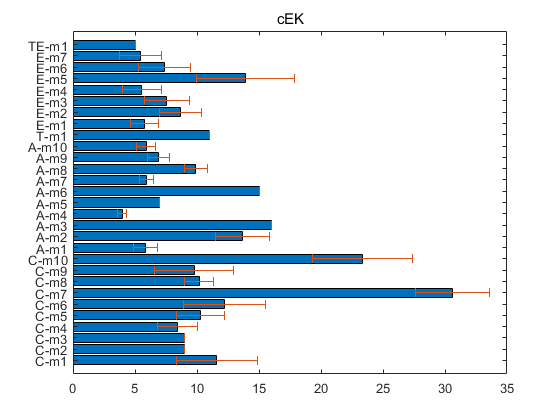







% number of motifs in each domain type (C, A, T, E, TE)
maxmotifnum=[10,10,1,7,1];


% generate/load distance structure for motifs
for k=1
    if k==1
        motif_struct=cEK_motif_struct; datastr='cEK';
    elseif k==2
        motif_struct=mibig_motif_struct; datastr='mibig';
    end
    motif_struct.motifid_mat_list = [floor(motif_struct.motifid_mat_list(:,1)),motif_struct.motifid_mat_list(:,2)];

    % length of all seqs
    for i=1:length(motif_struct.seq_list)
        motif_struct.seqlen_aa(i,1)=length(motif_struct.seq_list{i});
    end

    [motif_struct.uni_motifids,~,motif_struct.mids]=unique(motif_struct.motifid_mat_list,'rows');
    len_mean_var=zeros(size(motif_struct.uni_motifids,1),2);
    uni_motifstrs=[];
    for i=1:size(motif_struct.uni_motifids,1)
        seq_thism=find(motif_struct.mids==i);
        len_mean_var(i,1)=mean(motif_struct.seqlen_aa(seq_thism));
        len_mean_var(i,2)=var(motif_struct.seqlen_aa(seq_thism));

        if motif_struct.uni_motifids(i,1)>0
            uni_motifstrs{i,1}=cEK_omains.domaintypelist{motif_struct.uni_motifids(i,1)};
        else
            uni_motifstrs{i,1}='-';
        end

        if motif_struct.uni_motifids(i,2)==fix(motif_struct.uni_motifids(i,2))
            uni_motifstrs{i,1}=[uni_motifstrs{i,1},'-m',num2str(motif_struct.uni_motifids(i,2))]; % is a motif
        else
            uni_motifstrs{i,1}=[uni_motifstrs{i,1},'-',num2str(motif_struct.uni_motifids(i,2))];
        end
    end

    figure;
    ismotif=find(abs(round(motif_struct.uni_motifids(:,2))-motif_struct.uni_motifids(:,2))<0.001   & motif_struct.uni_motifids(:,1)>0);
    barh(1:length(ismotif),len_mean_var(ismotif,1));
    hold on;
    errorbar(len_mean_var(ismotif,1),1:length(ismotif),sqrt(len_mean_var(ismotif,2)),'horizontal','linestyle','none')
    set(gca,'ytick',1:length(ismotif),'yticklabel',uni_motifstrs(ismotif))
    title(datastr)

    % generate distance structures for motifs and intermotif region
    for i=1:size(motif_struct.uni_motifids,1)

        mlist=find(motif_struct.mids==i);
        struct_name=['\output1\',datastr,'_motif_',num2str(motif_struct.uni_motifids(i,1)),'_',num2str(motif_struct.uni_motifids(i,2)),'_',num2str(length(mlist))];

        if exist([pwd,struct_name,'.mat'],'file')
            raw=load([pwd,struct_name,'.mat']);
            diststruct=raw.diststruct;
            motif_struct.motif_diststruct{i}=diststruct;
            clear raw;
        else
            fprintf('generating %s....\n',struct_name)

            seqs=motif_struct.seq_list(mlist);
            loc_empyty_index=find(cellfun(@isempty,seqs));
            seqs(loc_empyty_index)={'A'};% 将全空序列处用A来占位
            if length(seqs)>1
                test_header = cellstr(num2str([1:length(seqs)]'));
                fastawrite([pwd,struct_name,'.fasta'],test_header,seqs);
                command = ['clustalo -i ',pwd,struct_name,'.fasta -o ',pwd,struct_name,'_1.fasta --outfmt fasta --output-order input-order'];
                system(command);

                try
                    msa=[];
                    raw = fastaread([pwd,struct_name,'_1.fasta']);
                    for ii = 1:length(raw)
                        msa=[msa;raw(ii).Sequence];
                    end
                catch ME
                    msa = multialign(seqs,'ScoringMatrix',scoringlist{2});
                end
            else
                msa = seqs{1};
            end
            for kkk = 1:length(loc_empyty_index)
                msa(loc_empyty_index(kkk),:)=strrep(msa(loc_empyty_index(kkk),:),'A','-');% 将占位的A去掉
            end


            diststruct=[];
            diststruct.mlist=mlist;
            diststruct.olist=motif_struct.omains_id(mlist);
            diststruct.motifidtype=motif_struct.uni_motifids(i,:);


            diststruct.msa=msa;
            motif_struct.motif_diststruct{i}=diststruct;

            save([pwd,struct_name,'.mat'],'diststruct');

        end % exist(stut_name,'file')


        % calculate distance by the msa
        if ~isfield(motif_struct.motif_diststruct{i},'distline')
            filepath=['output1/distlineby_msa_',datastr,'_',num2str(motif_struct.uni_motifids(i,1)),'_',num2str(motif_struct.uni_motifids(i,2)),'_',sprintf('%0.0f',mean(mlist)),'.txt'];

            if size(diststruct.msa,1)>1
                if ~exist(filepath,'file')
                    fprintf('calculating distance %d in %d....\n',i,size(motif_struct.uni_motifids,1));
                    distline=seqpdist(diststruct.msa,'method','p-distance');
                    dlmwrite(filepath,distline);
                else
                    distline=dlmread(filepath);
                end
            else
                distline=[];
            end
            % don't have to load it now
            motif_struct.motif_diststruct{i}.distline=distline;
        end
    end


    if k==1
        cEK_motif_struct=motif_struct;
    elseif k==2
        mibig_motif_struct=motif_struct; datastr='mibig';
    end

end


toc

历时 1.276319 秒。


Revise according to the updated results from Laura

Table S1 Data



cEK_regions.product={'S-S-G-L-D-A';
    'S-I-G-G';
    'W-P-L-I-F/O-P';
    'F';
    'L-N-G-L-V';
    'T-L-V-S-V-G-L-P-G-I';
    'F-T-L-P-Y-G';
    'V-T-V-V-P-O-I-T-I-V-F-Dhb-V';
    'P-P';
    'F-T-L-F-L-T-S';
    'Y-S-F-L-P-T-G';
    'F-P-A-V-N-Y';
    'G-T-Y-W-T-I-V'
    'A-A-L-P-L-W'
    'D-F-S-V-P-S-L-F-K-P'
    'G-T-W-S-Y-D/N'
    'A-W-D/N-F'
    'W-P-R'
    'S-F-I-I-R-I'
    'F-T-Y-R-Y-I'
    };


% assign colors

deadclusters=find(cEK_regions.fateid==0);
cEK_regions.cluster_colors(deadclusters,:)=0*cEK_regions.cluster_colors(deadclusters,:)+0.2; % dead ones are in deep gray
okcluster=find(cEK_regions.fateid~=0);
colortables=cbrewer('qual','Set1',length(okcluster)+1);

ori_colors=cEK_regions.cluster_colors;
cEK_regions.cluster_colors(okcluster,:)=colortables(1:(length(colortables)-1),:);
tempcolor=cEK_regions.cluster_colors(8,:);
cEK_regions.cluster_colors(8,:)=cEK_regions.cluster_colors(3,:);
cEK_regions.cluster_colors(3,:)=tempcolor;

cEK_regions.cluster_colors(11,:)=[0,102,0]/255;
cEK_regions.cluster_colors(13,:)=[0,255,255]/255;
cEK_regions.cluster_colors(19,:)=[255,0,255]/255;


cEK_regions.cluster_colors=max(0,min(1,cEK_regions.cluster_colors));

##  Sequence Covariation

cEK_omains.moduleid=zeros(cEK_omains.num,1); %CAT (including the interdomains before C as a module). Use C as the locator
for c=1:cEK_regions.num
    olist=find(cEK_omains.region_ids==c);
    beforeClocs=find(cEK_omains.isdomain(olist)==0 & cEK_omains.typeid_mat(olist,2)==Ctype); % before C interdomain
    beforeClocs(1)=1;
    beforeClocs=[beforeClocs;length(olist)+1];

    olist_moduleids=0*olist;
    for m=1:(length(beforeClocs)-1)
        soloc=beforeClocs(m);
        eoloc=beforeClocs(m+1)-1;
        olist_moduleids(soloc:eoloc)=m;
    end

    cEK_omains.moduleid(olist)=olist_moduleids;
    %for i=1:length(olist_moduleids)
    %    fprintf('%s\t%d\n',cEK_omains.inforstr{olist(i)},olist_moduleids(i))
    %end
    %fprintf('\n')
end

% construct "module distance" betwen all differnt omains: not same cluster: nan; same cluster: m(i,j)=m1-m2;
cEK_omains.modulediff_m=nan*zeros(cEK_omains.num,cEK_omains.num);
for c=1:cEK_regions.num
    o_thisc=find(cEK_omains.region_ids==c);
    for i=1:length(o_thisc)
        oi=o_thisc(i);
        for j=1:length(o_thisc)
            oj=o_thisc(j);
            cEK_omains.modulediff_m(oi,oj)=cEK_omains.moduleid(oi)-cEK_omains.moduleid(oj);
        end
    end
end


##  Load the updated A domain specificity data


cEK_omains.updated_specificity=[];
for i=1:cEK_omains.num
    cEK_omains.updated_specificity{i,1}='-';
    cEK_omains.updated_pred{i,1}='-';
    cEK_omains.updated_obs{i,1}='-';
    cEK_omains.updated_productstr{i,1}='-';
end


datapath='./output1/cEK_A2-unit_aa_pred(obs).fasta';
rawfasta=fastaread(datapath);

for i=1:length(rawfasta)
    headstr=rawfasta(i).Header;
    headstr(1:5)=[];
    smallseq=rawfasta(i).Sequence;
    strlist=strsplit(headstr,'_');
    NRPSid=str2num(strlist{1});
    moduleid=str2num(strlist{2}(2:end));
    specificity=strlist{3};


    loc=find(cEK_omains.region_ids==NRPSid & cEK_omains.moduleid==moduleid & cEK_omains.typeid_mat(:,1)==Atype & cEK_omains.isdomain==1);

    if ~isempty(loc) && cEK_regions.fateid(NRPSid)>0
        % confirm that the sequence is correct
        bracketloc_1=find(specificity=='(');
        if isempty(bracketloc_1) % no obsered
            pred_str=specificity;
            obs_str='NA';
        else
            pred_str=specificity(1:(bracketloc_1-1));
            obs_str=specificity((bracketloc_1+1):(end-1));
        end
        cEK_omains.updated_specificity{loc,1}=specificity;
        cEK_omains.updated_pred{loc,1}=pred_str;
        cEK_omains.updated_obs{loc,1}=obs_str;


        % sanity check
        omainseq=cEK_omains.seq_ntaa{loc,2};
        if (strfind(omainseq,smallseq)<0)
            error('wrong seq location')
        end
    end
end

% A domains
Adlist=find(ismember(cEK_omains.typeid_mat,[Atype,0],'rows'));

% A domains in the 9 known active clusters
Aactive=Adlist(strcmp(cEK_regions.fate(cEK_omains.region_ids(Adlist)),'Active'));

% A domains with observed specificity
Aobserved=Adlist(~strcmp(cEK_omains.updated_obs(Adlist),'-') & ~strcmp(cEK_omains.updated_obs(Adlist),'NA'));

% A domains with predicted specificity
Apredicted=Adlist(~strcmp(cEK_omains.updated_pred(Adlist),'-'));

% A domains with predicted specificituy
fprintf('Number of all A domains: %d\n',length(Adlist));

Number of all A domains: 120


fprintf('Number of A domains in active clusters: %d\n',length(Aactive));

Number of A domains in active clusters: 65


fprintf('Number of A domains predicted: %d\n',length(Apredicted));

Number of A domains predicted: 102


fprintf('Number of A domains observed: %d\n',length(Aobserved));

Number of A domains observed: 65




fprintf('Fate(cID)\tproduct\tpredicted\tobserved\n')

Fate(cID)	product	predicted	observed


for c=1:cEK_regions.num
    productstrlist=strsplit(cEK_regions.product{c},'-');
    As_thisc=Adlist(cEK_omains.region_ids(Adlist)==c);
    for i=1:length(As_thisc)
        cEK_omains.updated_productstr{As_thisc(i),1}=productstrlist{i};

        if  ~strcmp(cEK_omains.updated_productstr{As_thisc(i),1},cEK_omains.updated_pred{As_thisc(i),1})
            if ~strcmp(cEK_regions.fate{c},'Dead')
                fprintf('%s(%d)\t%s\t%s\t%s\n',cEK_regions.fate{c},c,cEK_omains.updated_productstr{As_thisc(i),1},cEK_omains.updated_pred{As_thisc(i),1},cEK_omains.updated_obs{As_thisc(i),1})
            end
        end
    end
end

looks good(1)	S	X	NA
looks good(1)	S	X	NA
looks good(1)	A	X	NA
looks dead(2)	S	-	-
looks dead(2)	I	-	-
looks dead(2)	G	-	-
looks dead(2)	G	-	-
looks good(3)	W	X	NA
looks good(3)	I	T	NA
looks good(3)	F/O	X	NA
looks dead(4)	F	-	-
looks good(5)	L	X	NA
looks good(5)	N	D	NA
looks good(5)	V	A	NA
looks good(6)	V	A	NA
looks good(6)	S	X	NA
looks good(6)	V	A	NA
looks good(6)	I	T	NA
looks dead(7)	F	-	-
looks dead(7)	T	-	-
looks dead(7)	L	-	-
looks dead(7)	P	-	-
looks dead(7)	Y	-	-
looks dead(7)	G	-	-
Active(8)	V	A	V
Active(8)	V	A	V
Active(8)	V	A	V
Active(8)	O	X	O
Active(8)	I	T	aI
Active(8)	I	T	aI
Active(8)	V	A	V
Active(8)	F	X	F
Active(8)	Dhb	T	DB
Active(8)	V	A	V
looks dead(9)	P	-	-
looks dead(9)	P	-	-
Active(10)	F	X	F
Active(10)	F	X	F
Active(10)	S	X	S
Active(11)	Y	X	Y
Active(11)	S	T	S
Active(11)	F	X	F
Active(12)	F	X	F
Active(12)	A	X	A
Active(12)	V	A	V
Active(12)	N	D	N
Active(12)	Y	X	Y
Active(13)	Y	X	Y
Active(13)	W	X	W
Active(13)	I	T	I
Active(13)	V	A	V
Active(14)	A	X	A
Active(14)	A	X	A
Active(14)	


% specify the specificity ID for A domains, only for the 9 active ones
majorspecificity=cEK_omains.updated_obs(Aactive);
for i=1:length(majorspecificity)
    sstr=majorspecificity{i};

    loc=strfind(majorspecificity{i},'+');
    if ~isempty(loc)
        majorspecificity{i}=sstr(1:(loc-1));
    end

    if (sstr(1)=='a')
        majorspecificity{i}=sstr(2:end);
    end

end
tabulate(majorspecificity)

  Value    Count   Percent
      V        8     12.31%
      T        8     12.31%
      P        7     10.77%
      O        1      1.54%
      I        4      6.15%
      F        8     12.31%
     DB        1      1.54%
      L        6      9.23%
      S        4      6.15%
      Y        5      7.69%
      G        2      3.08%
      A        3      4.62%
      N        1      1.54%
      W        3      4.62%
      D        1      1.54%
      K        1      1.54%
      R        2      3.08%



cEK_omains.specificity_id=0*cEK_omains.specificity_id;
cEK_omains.specificity_unistrs=[];
for i=1:26
    cEK_omains.specificity_unistrs{i,1}=int2aa(i);
end

for i=1:length(majorspecificity)
    x=aa2int(majorspecificity{i});
    if length(x)==1 & x>0

        cEK_omains.specificity_id(Aactive(i))=x;


    else
        if strcmp(majorspecificity{i},'DB')
            cEK_omains.specificity_id(Aactive(i))=length(cEK_omains.specificity_unistrs)+1;
            cEK_omains.specificity_unistrs{end+1,1}=majorspecificity{i};
        elseif strcmp(majorspecificity{i},'O')
            cEK_omains.specificity_id(Aactive(i))=length(cEK_omains.specificity_unistrs)+1;
            cEK_omains.specificity_unistrs{end+1,1}=majorspecificity{i};
        else

            error('wrong code')
        end
    end
end



Load the observed TE and Cs data

## Data source and structure

%%%%%%%%%%%%%%%%%
goodcEKrlist=find(cEK_regions.fateid>0);


%choose the data: mibig or cEK
%motif_struct=mibig_motif_struct;datastr='mibig';goodrlist=goodmibigrlist;omains=mibig_omains;
motif_struct=cEK_motif_struct;datastr='cEK';goodrlist=goodcEKrlist;omains=cEK_omains;

fprintf('(%d) regions, (%d) domains\n',length(goodrlist),sum( omains.isdomain & ismember(omains.region_ids,goodrlist)))

(15) regions, (369) domains


Structure of domains

% for each motif, the C_oid, it is before or after, motif_struct.C_oid_ab
motif_struct.Csubtype_ab=[];%
motif_struct.Aoid_ab=[];

uniregions=unique(motif_struct.region_id);
for r=1:length(uniregions)
    rid=uniregions(r);
    olist_C_thisr=find(omains.region_ids==rid & omains.typeid_mat(:,1)==Ctype & omains.typeid_mat(:,2)==0);
    olist_A_thisr=find(omains.region_ids==rid & omains.typeid_mat(:,1)==Ctype & omains.typeid_mat(:,2)==0);

    mlist=find(motif_struct.region_id==rid);
    for i=1:length(mlist)
        mid=mlist(i);
        oid=motif_struct.omains_id(mid);% omain it belongs to

        dtype=motif_struct.motifid_mat_list(mid,1);
        mtype=motif_struct.motifid_mat_list(mid,2);

        % for Chriality subtype
        if dtype==Ctype && mtype>0.5 && mtype<maxmotifnum(dtype)  % within the range
            motif_struct.Csubtype_ab{mid,1}=omains.subtypestr{oid};
            motif_struct.Csubtype_ab{mid,2}=omains.subtypestr{oid};
        elseif dtype==Ctype && mtype==0.5 % the region before C
            cbefore=max(olist_C_thisr(olist_C_thisr<oid));
            if ~isempty(cbefore)
                motif_struct.Csubtype_ab{mid,1}=omains.subtypestr{cbefore};
            else
                motif_struct.Csubtype_ab{mid,1}='S-';
            end
            motif_struct.Csubtype_ab{mid,2}=omains.subtypestr{oid};

        elseif dtype==Ctype && mtype==maxmotifnum(dtype)
            cafter=min(olist_C_thisr(olist_C_thisr>oid));
            motif_struct.Csubtype_ab{mid,1}=omains.subtypestr{oid};
            if ~isempty(cafter)
                motif_struct.Csubtype_ab{mid,2}=omains.subtypestr{cafter};
            else
                motif_struct.Csubtype_ab{mid,2}='E-'; % ending type
            end
        else
            cbefore=max(olist_C_thisr(olist_C_thisr<oid));
            cafter=min(olist_C_thisr(olist_C_thisr>oid));
            if ~isempty(cbefore)
                motif_struct.Csubtype_ab{mid,1}=omains.subtypestr{cbefore};
            else
                motif_struct.Csubtype_ab{mid,1}='S-'; % start
            end
            if ~isempty(cafter)
                motif_struct.Csubtype_ab{mid,2}=omains.subtypestr{cafter};
            else
                motif_struct.Csubtype_ab{mid,2}='E-';
            end

        end

    end
end


The motif type before a motif

% if the motif has standard structure
motif_struct.motif_type_before=zeros(size(motif_struct.motifid_mat_list,1),1); % 0: start
for i=2:size(motif_struct.motifid_mat_list,1)
    mb=i-1;
    if motif_struct.region_id(mb)==motif_struct.region_id(i) % only when they are in the same region
        searchtype=motif_struct.motifid_mat_list(mb,:);
        motif_struct.motif_type_before(i)=find(ismember(motif_struct.uni_motifids,searchtype,'rows'));
    end
end

for dtype=1:5
    m_list=find(ismember(motif_struct.region_id,goodrlist) & ismember(motif_struct.motifid_mat_list,[dtype,0.5],'rows'));
    tabfreq=tabulate(motif_struct.motif_type_before(m_list));
    [~,order]=sort(tabfreq(:,2),'descend');

    fprintf('%s\n',omains.domaintypelist{dtype});

    for i=1:size(tabfreq,1)
        if tabfreq(order(i),2)>0
            o=tabfreq(order(i),1);
            if o==0
                beforetypestr='Start';
            else
                beforetypestr=[omains.domaintypelist{motif_struct.uni_motifids(o,1)},num2str(motif_struct.uni_motifids(o,2))];
            end
            fprintf(['%s\t%d\t%d\n'],beforetypestr,o,tabfreq(order(i),2))
        end
    end
end

C


E7	59	43
T1	44	38
Start	0	14
T1.5	45	3
E7.5	60	3
TE1.5	63	1


A


C10	20	100
C10.5	21	2


T


A10	41	101
A10.5	42	1


E


T1	44	46


TE


T1	44	14
Start	0	1



stardard_msbefore={[44, 59, 0] % C: T1, E7, START
    [20, 0]% A C10, start A
    41 %T
    44 % E
    44 % TE
    };



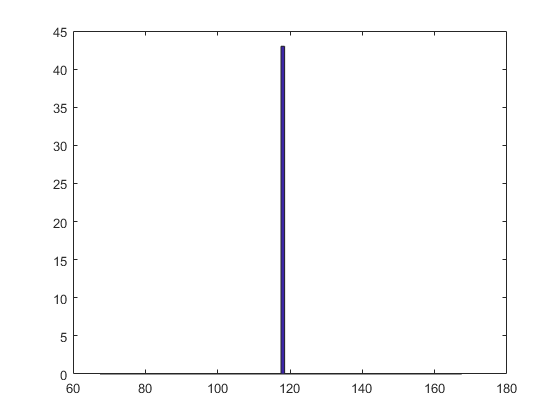

% check the length of the "before" type
dtype=Ctype;
k=2;

standardlist=stardard_msbefore{dtype};
m_list=find(ismember(motif_struct.region_id,goodrlist) & ismember(motif_struct.motifid_mat_list,[dtype,0.5],'rows') & motif_struct.motif_type_before==standardlist(k));
figure;
hist(motif_struct.seqlen_aa(m_list),100)

C-0.5: three possibilities: start-C , or E7-C1, or T1-C1 (1,2,3), WHICH DIFFERS A LOT IN LENGTH

A-0.5: two be:  start-A,  C10-A1 (1,2)

T-0.5: should be: A10-T1 (1) 

E-0.5: should be: C9-E1 (1)

TE-0.5: 1  possibilities: T1-C1

## Boarders of domains

for each domains, their position in motifs: which motif, and which residue of that motif

omains.motifposi_se=nan*zeros(omains.num,2,2);
dmains_in_motifs=unique(motif_struct.omains_id);
dmains_in_motifs=dmains_in_motifs(omains.isdomain(dmains_in_motifs)==1);
for o=1:length(dmains_in_motifs)
    did=dmains_in_motifs(o);


    domain_seq=omains.seq_ntaa{did,2};


    % motifs with this omain's information
    mlist_thisdomain=find(motif_struct.omains_id==did);
    mlist_thisdomain=[mlist_thisdomain;mlist_thisdomain(end)+1];
    combinedseq=[motif_struct.seq_list{mlist_thisdomain}];
    combined_se=zeros(length(mlist_thisdomain),2);
    startlen=1;
    for i=1:length(mlist_thisdomain)
        combined_se(i,1)=startlen;
        combined_se(i,2)=startlen+length(motif_struct.seq_list{mlist_thisdomain(i)})-1;
        startlen=combined_se(i,2)+1;
    end

    startloc=strfind(combinedseq,domain_seq);
    stoploc=startloc+length(domain_seq)-1;



    if ~isempty(startloc) &&  strcmp(combinedseq(startloc:stoploc),domain_seq)
        domainse=[startloc,stoploc];
        for k=1:2
            seqid=find(~(combined_se(:,1)>domainse(k)) & ~(combined_se(:,2)<domainse(k)))';

            omains.motifposi_se(did,1,k)=mlist_thisdomain(seqid);
            omains.motifposi_se(did,2,k)=(domainse(k)-combined_se(seqid,1)+1);

        end
    else
        error('wrong')
    end
end



where each domain starts and ends


domainse_mlist=[]; % motifs that contain start/end position for a type of domain
for dtype=1:5

    fprintf('for domain %s\n',omains.domaintypelist{dtype})
    domainlist=dmains_in_motifs(omains.typeid_mat(dmains_in_motifs,1)==dtype);

    for k=[1,2]
        mlist=omains.motifposi_se(domainlist,1,k);
        domainse_mlist{dtype,k}=mlist;

        [unitype,~,repid]=unique(motif_struct.motifid_mat_list(mlist,:),'rows');
        tabfreq=tabulate(repid);tabfreq=tabfreq(tabfreq(:,2)>0,:);
        [~,order]=sort(tabfreq(:,2),'descend');
        if k==1
            fprintf('starts in \n')
        else
            fprintf('ends in\n')
        end
        for o=1:length(order)
            mtype=unitype(order(o),:);
            fprintf('%d-%0.2f\t%f\n',mtype(1),mtype(2),tabfreq(order(o),3));
        end
    end
end

for domain C


starts in 


1-0.50	81.666667
1-1.00	10.833333
1-1.50	7.500000


ends in


1-7.50	84.166667
1-7.00	15.000000
1-3.50	0.833333


for domain A


starts in 


2-1.00	97.500000
2-2.50	2.500000


ends in


2-8.50	99.166667
2-6.50	0.833333


for domain T


starts in 


3-0.50	100.000000


ends in


4-0.50	44.537815
1-0.50	36.974790
5-0.50	14.285714
3-1.50	4.201681


for domain E


starts in 


4-0.50	96.363636
4-2.50	3.636364


ends in


4-5.50	76.363636
4-5.00	16.363636
4-2.50	5.454545
4-3.50	1.818182


for domain TE


starts in 


5-0.50	100.000000


ends in


5-1.50	100.000000


## R1: overall structure of C\A\T\E\TE domain

(120)C domains


size of calculation in domain type 1


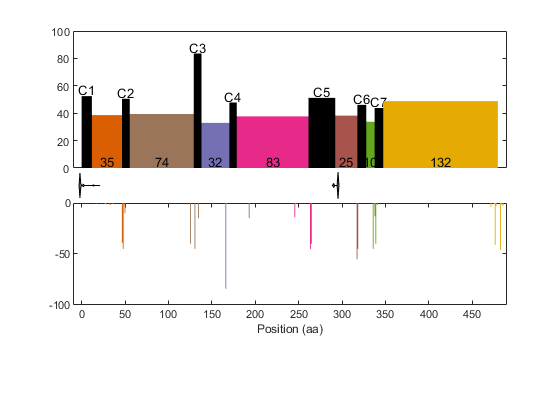

(120)A domains


size of calculation in domain type 2


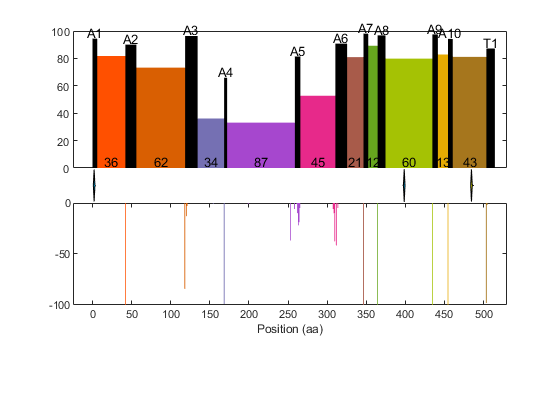

(119)T domains
(55)E domains


size of calculation in domain type 4


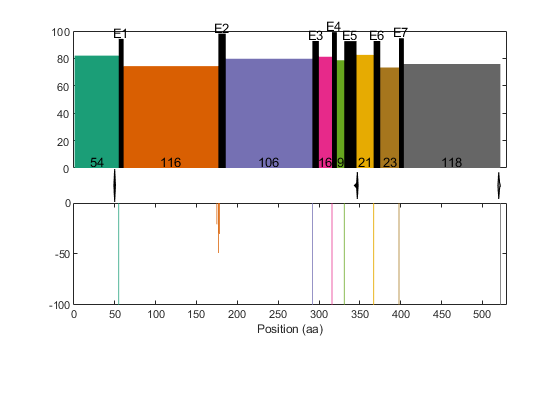

(18)TE domains


 
----------------------------------------------------------------------
The minimum number of colors for table *Dark2* is 3
This minimum value shall be defined as ncol instead
----------------------------------------------------------------------
 


size of calculation in domain type 5


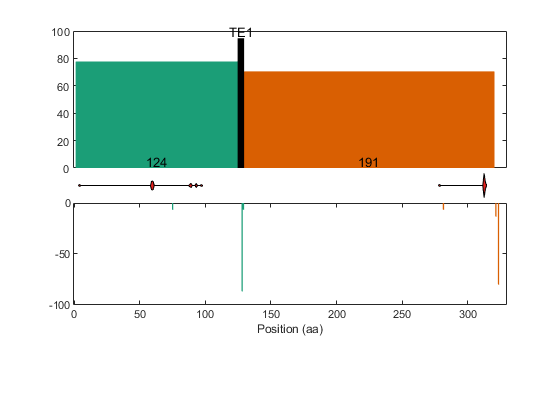


savemotiffig=0;
gen_lengthdistri=0;
gen_logo=0;
gen_struct=1;

for dtype=1:5
    % for dtype=1
    dlist=find(omains.isdomain & omains.typeid_mat(:,1)==dtype);
    fprintf('(%d)%s domains\n',length(dlist),omains.domaintypelist{dtype})
    %%%%%%%%%%% draw length distribution
    if gen_lengthdistri
        figure;
        fs=20;
        subplotnum=1;
        switch dtype
            case Ctype
                lenlist=250:5:500;
            case Atype
                lenlist=350:5:500;
            case Ttype
                lenlist=55:1:75;
            case TEtype
                lenlist=100:300;
            case Etype
                lenlist=250:5:500;
        end

        subplot(subplotnum,1,1)
        if isfield(omains,'aalen')
            hist(omains.aalen(dlist),lenlist);
        else
            hist(omains.aaseqlen(dlist),lenlist);
        end
        title(sprintf('MIBIG NPRS %s domain',omains.domaintypelist{dtype}))
        set(gca,'fontsize',fs)
        xlim([min(lenlist),max(lenlist)])

        if subplotnum==2
            subplot(subplotnum,1,2)
            hist(Pfamstruct.seqlen,lenlist)
            set(gca,'fontsize',fs)
            xlabel('length(aa)')
            title(sprintf('Pfam NPRS %s domain',omains.domaintypelist{dtype}))
            xlim([min(lenlist),max(lenlist)])
        end
    end

    %%%%%%%%%%%%%%% draw logos
    % if there were C
    if gen_logo
        c_o_list=find(omains.typeid_mat(:,1)==Ctype & omains.typeid_mat(:,2)==0);
        [C_subtypes_strs,~,c_o_subtypeids]=unique(omains.subtypestr(c_o_list));
        omain_subtypeids=nan*zeros(1,max(c_o_list));
        omain_subtypeids(c_o_list)=c_o_subtypeids;

        for m=1:maxmotifnum(dtype)
            %         if dtype==1
            %             m=8;
            loc_in_uni=find(ismember(motif_struct.uni_motifids,[dtype,m],'rows'));
            diststruct=motif_struct.motif_diststruct{loc_in_uni};

            mlist=diststruct.mlist;
            olist=diststruct.olist;

            % which of these belong to "goodr"
            belongtogoodr=find(motif_struct.seqlen_aa(mlist)>0 & ismember(omains.region_ids(olist),goodrlist));
            %             struct_name = ['\output\',datastr,'_good_motif_',num2str(motif_struct.uni_motifids(loc_in_uni,1)),'_',num2str(motif_struct.uni_motifids(loc_in_uni,2)),'_',num2str(length(mlist))];
            %
            %             raw=load([pwd,struct_name,'.mat']);
            %             ma=raw.ma;
            %             clear raw;
            belongtogoodseq=motif_struct.seq_list(mlist(belongtogoodr));
            ma=[];
            loc_max_len=max(motif_struct.seqlen_aa(mlist));
            for kkk = 1:length(belongtogoodr)
                ma=[ma;[belongtogoodseq{kkk},repelem('-',loc_max_len-length(belongtogoodseq{kkk}))]];
            end

            gapthressh=0.9;
            weight_thresh=-1;
            columntokeep=find(sum(ma=='-')/size(ma,1)<gapthressh);
            if dtype~=Ctype
                figure;
                %                 gapthressh=0.9;
                %                 weight_thresh=-1;
                %                 columntokeep=find(sum(ma=='-')/size(ma,1)<gapthressh);

                SeqLogo_HRL(ma(:,columntokeep),'AA',aa_colormaping,letterclass,weight_thresh);
                xlim([0.5,length(columntokeep)+0.5])
                %             set(gca,'fontsize',fs);
                set(gca,'fontsize',25);
                %set(gca,'xtick',1:length(columntokeep),'xticklabel',meanactualp_str(columntokeep))
                % title([cEK_omains.domaintypelist{dtype},' motif (',num2str(m),datastr,')'])
                title([cEK_omains.domaintypelist{dtype},' ',num2str(m)])
                ylim([0,4.4]);
                if savemotiffig
                    figpath=['./Figures/Fig1/',cEK_omains.domaintypelist{dtype},'_',num2str(m),'_',datastr,'.eps'];
                    saveas(gcf,figpath,'epsc');
                end


                %figure
                %histogram(ma_str_len)
                %title([cEK_omains.domaintypelist{dtype},' ',num2str(m),' ',num2str(size(ma,1)-length(ma_str_clean)),' ',num2str(round(length(ma_str_clean)/size(ma,1),3))])

                %             if dtype==Ctype
            else
                figure;
                if max(omain_subtypeids)==6
                    sequenceofC=[4,2,5,3,1,6];
                else
                    sequenceofC=[2,1,3];
                end
                loc_seq_list=cell(length(sequenceofC),1);
                ma2=[];
                for j= 1:length(sequenceofC)
                    if j ==6
                        j;
                    end
                    u=sequenceofC(j);
                    list=find(omain_subtypeids(olist(belongtogoodr))==u);

                    if length(list)>2
                        ma_2_use=ma(list,columntokeep);
                        if (m==1&&(j == 1||j == 3||j == 5))||(m==4&&(j==2||j==6))||(m==7&&j==6)||(m==9&&(j==2||j==3))
                            ma_2_use=[repelem('-',size(ma_2_use,1))',ma_2_use(:,1:end-1)];%开头退一格
                        elseif (m==4&&j==3)||(m==8&&j==6)%开头退两格
                            ma_2_use=[repelem('-',size(ma_2_use,1))',repelem('-',size(ma_2_use,1))',ma_2_use(:,1:end-2)];
                        elseif m==7&&(j==1||j==3)
                            ma_2_use=[ma_2_use(:,1:12),repelem('-',size(ma_2_use,1))',repelem('-',size(ma_2_use,1))',ma_2_use(:,13:end-2)];
                        end
                        ma2=[ma2;ma_2_use];

                        gapthressh=1.9;
                        %                         subplot(length(C_subtypes_strs),2,j)
                        subplot(length(C_subtypes_strs),1,j)

                        [~,loc_seq_list{j}]=SeqLogo_HRL(ma_2_use,'AA',aa_colormaping,letterclass,weight_thresh);
                        titlestr=['(',num2str(length(list)),')',C_subtypes_strs{u}]; titlestr(titlestr=='_')=' ';
                        title(titlestr)
                        %                         subplot(length(C_subtypes_strs),2,j+length(C_subtypes_strs))
                        %                         histogram(ma_str_len)
                        %                         title([titlestr,' ',num2str(length(list)-length(ma_str_clean)),' ',num2str(round(length(ma_str_clean)/length(list),3))])
                    end
                    xlim([0.5,length(columntokeep)+0.5])
                    %                     ylim([0,4.4])
                    %set(gca,'xtick',1:length(columntokeep),'xticklabel',meanactualp_str(columntokeep))

                    %                     set(gca,'xtick',[],'ytick',[])

                    if  savemotiffig
                        figpath=['./Figures/Fig1/',cEK_omains.domaintypelist{dtype},'_bysubtype_',num2str(m),'_',datastr,'.eps'];
                        saveas(gcf,figpath,'epsc')
                    end
                end
                figure;
                gapthressh=0.9;
                weight_thresh=-1;
                columntokeep=find(sum(ma2=='-')/size(ma2,1)<gapthressh);

                SeqLogo_HRL(ma2(:,columntokeep),'AA',aa_colormaping,letterclass,weight_thresh);
                xlim([0.5,length(columntokeep)+0.5])
                %             set(gca,'fontsize',fs);
                set(gca,'fontsize',25);
                %set(gca,'xtick',1:length(columntokeep),'xticklabel',meanactualp_str(columntokeep))
                % title([cEK_omains.domaintypelist{dtype},' motif (',num2str(m),datastr,')'])
                title([cEK_omains.domaintypelist{dtype},' ',num2str(m)])
                ylim([0,4.4]);
                if savemotiffig
                    figpath=['./Figures/Fig1/',cEK_omains.domaintypelist{dtype},'_',num2str(m),'_',datastr,'.eps'];
                    saveas(gcf,figpath,'epsc');
                end

                %                 fastawrite(['output/',cEK_omains.domaintypelist{dtype},num2str(m),'.fasta'],C_subtypes_strs(sequenceofC),loc_seq_list)
            end % if dtype==Ctype
        end % for m=1:maxmotifnum(dtype)
    end

    if gen_struct && dtype~=Ttype

        if ismember(dtype,[Ctype,Atype])
            showstartregion=0;
        else
            showstartregion=1;
        end


        violinscale=10;
        startlen=1;
        if dtype==Atype
            colortables=cbrewer('qual','Dark2',maxmotifnum(dtype)+3);
        else
            colortables=cbrewer('qual','Dark2',maxmotifnum(dtype)+1);

        end

        colortables=min(1,max(0,colortables));
        colorcount=0;

        mulinfor_x_y_colors=[];
        alone_motifmat_seonx=[];



        if dtype==Ctype
            motifstocheck=[1,2,3,4,7,8,9];
        else
            motifstocheck=1:maxmotifnum(dtype);
        end


        % first generate all types to check
        types_members=[];
        types_members{1}=[dtype,0.5];
        for i=1:length(motifstocheck)
            thism=motifstocheck(i);
            types_members{end+1}=[dtype,thism];

            if i~=length(motifstocheck)
                nextm=motifstocheck(i+1);
                sublist=((thism+0.5):0.5:(nextm-0.5))';
                types_members{end+1}=[dtype*ones(length(sublist),1),sublist];
            end
        end

        switch dtype
            case Ctype % ending with [1,9]
                types_members{end+1}= [1,9.5;
                    1,10;
                    Atype,0.5];% C-A inter, after C9 to A1
                boarders_to_show=[Ttype,2;
                    Etype,2;
                    Ctype,1;
                    Ctype,2;
                    Atype,1]; % 1: start, 2: stop
            case Atype % ending with [2,10]
                types_members{end+1}=[Ttype,0.5];
                types_members{end+1}=[Ttype,1]; % T motif
                % types_members{end+1}=[Ctype,0.5];

                boarders_to_show=[Atype,1;
                    Atype,2;
                    Ttype,1;
                    Ttype,2;
                    Ctype,1]; % 1: start, 2: stop

            case Etype % ending with [2,10]
                %types_members=[[Etype,0.5],types_members]; % start with "before E" regions
                types_members{end+1}=[Ctype,0.5]; % end with regions before C
                boarders_to_show=[Etype,1;
                    Etype,2;
                    Ctype,1];
            case TEtype
                %types_members=[[TEtype,0.5],types_members]; % start with "before E" regions
                types_members{end+1}=[TEtype,1.5];
                boarders_to_show=[TEtype,1;
                    TEtype,2;
                    ];
        end

        boarders_posi=[];
        for i=1:size(boarders_to_show,1)
            boarders_posi{i}=[];
        end

        % use the first motif of the domain as a "locator", construct the m_mats for
        % all.
        combined_types=[];
        combined_piecesid=[];
        for i=1:length(types_members)
            combined_piecesid=[combined_piecesid;i*ones(size(types_members{i},1),1)];
            combined_types=[combined_types;types_members{i}];
        end

        mlist_firstmotif=find(ismember(motif_struct.region_id,goodrlist) & ismember(motif_struct.motifid_mat_list,[dtype,1],'rows'));
        loc_firstmotif=find(ismember(combined_types,[dtype,1],'rows'));

        motif_mats=zeros(length(mlist_firstmotif),size(combined_types,1)); % all motifs related to this one
        badmlist=[];
        for i=1:length(mlist_firstmotif)
            for j=1:size(combined_types,1)
                shouldbe_mid = mlist_firstmotif(i)+j-loc_firstmotif;
                if ismember(motif_struct.motifid_mat_list(shouldbe_mid,:),combined_types(j,:),'rows')
                    motif_mats(i,j)=shouldbe_mid;
                else
                    badmlist(end+1)=i;
                end
            end
        end %for i=1:length(m_list)
        motif_mats(badmlist,:)=[];

        % define specificity for the mat, according to the second motif
        second_olist=motif_struct.omains_id(motif_mats(:,2));
        if dtype==Ctype
            [~,~,mat_specificity]=unique(omains.subtypestr(second_olist));
            %[~,~,mat_specificity]=unique(motif_struct.Csubtype_ab(motif_mats(:,2),1));
        elseif dtype==Atype
            %[~,~,mat_specificity]=unique(motif_struct.Csubtype_ab(motif_mats(:,2),2)); %chirality related to next C


            [~,~,mat_specificity]=unique(omains.specificity_id(second_olist));
        end

        fprintf('size of calculation in domain type %d\n',dtype)
        %%%%%%%%%%%%%% goes across motifs
        se_lens=zeros(length(types_members),2);
        meanid_list=zeros(length(types_members),1);
        colorcode_m=zeros(length(types_members),3);
        lenfreq_list=[];
        text_list=[];
        for m=1:length(types_members)
            t_members=types_members{m};
            starttype=t_members(1,:);


            m_mat=motif_mats(:,combined_piecesid==m);
            % use only m_mat from now on

            if abs(round(starttype(2))-starttype(2))>0.1 % not a motif
                colorcount=colorcount+1;
                colorcode=colortables(colorcount,:);
                ismotif=0;
            else % is a motif
                colorcode=[0,0,0];
                ismotif=1;
            end



            % length distribution
            lenslist=zeros(size(m_mat,1),1);
            for j=1:size(m_mat,1)
                lenslist(j)=sum(motif_struct.seqlen_aa(m_mat(j,:)));
            end

            mean_identities_alone=zeros(1,size(m_mat,2));
            mean_lens_alone=zeros(1,size(m_mat,2));
            lastlen=startlen;
            clear j
            for k=1:size(m_mat,2)
                thism_type=t_members(k,:);

                motifloc=find(ismember(motif_struct.uni_motifids,thism_type,'rows'));
                diststruct_mlist=motif_struct.motif_diststruct{motifloc}.mlist;
                diststruct_olist=motif_struct.motif_diststruct{motifloc}.olist;
                diststruct_distm=squareform(motif_struct.motif_diststruct{motifloc}.distline);
                diststruct_msa=motif_struct.motif_diststruct{motifloc}.msa;


                % only extract these in "good regions"
                diststruct_list_2_use=find(ismember(diststruct_mlist,m_mat(:,k)));

                % identity and length
                mean_identities_alone(k)=100*(1-nanmean(squareform(diststruct_distm(diststruct_list_2_use,diststruct_list_2_use))));
                mean_lens_alone(k)=mean(motif_struct.seqlen_aa(diststruct_mlist(diststruct_list_2_use)));

                %%%%% obtain mutual informations
                %[~,~,m_specificity]=unique(motif_struct.Csubtype_ab(diststruct_mlist(diststruct_list_2_use),2));
                loc_in_mmat=0*diststruct_list_2_use;
                for b=1:length(loc_in_mmat)
                    loc_in_mmat(b)=find(m_mat(:,k)==diststruct_mlist(diststruct_list_2_use(b)));
                end

                % calculate mutual information
                if 0 & ismember(dtype,[Ctype,Atype])
                    m_specificity=mat_specificity(loc_in_mmat);
                    msa=motif_struct.motif_diststruct{motifloc}.msa;
                    % obtain the mutual information in each line about the specificity
                    msa=msa(diststruct_list_2_use,:);
                    nanpercent=sum(msa=='-',1)/size(msa,1);


                    [value,order]=sort(nanpercent);nanthresh=max(0.5,value(ceil(mean_lens_alone(k))));
                    %[value,order]=sort(nanpercent)

                    msa=msa(:,nanpercent<nanthresh);
                    msa_num=aa2int(msa);
                    msa_num(msa=='-'|msa=='*')=nan;

                    fprintf('%f\t%f\t%f\n',nanthresh,size(msa,2),mean_lens_alone(k))



                    mulinfor_list=zeros(1,size(msa_num,2));
                    for s=1:size(msa_num,2)
                        nonzerolist=find(m_specificity>0);

                        [H1,H2,CH1_given2,CH2_given1,mulin]=ZL_Mulinfor_int(msa_num(nonzerolist,s),m_specificity(nonzerolist));
                        mulinfor_list(s)=mulin;
                    end

                    mulinfor_x_y_colors=[mulinfor_x_y_colors,[linspace(lastlen,lastlen+mean_lens_alone(k),length(mulinfor_list));
                        mulinfor_list;
                        (1-ismotif)*colorcount*ones(size(mulinfor_list))]];

                    alone_motifmat_seonx(end+1,:)=[thism_type,lastlen,lastlen+mean_lens_alone(k)];
                end


                %%%%%%%%%%%%%% location for domain boarders
                for i=1:size(boarders_to_show,1)
                    toshowd=boarders_to_show(i,1);
                    se=boarders_to_show(i,2);

                    dlist=find(omains.typeid_mat(:,1)==toshowd & omains.isdomain==1 & ismember(omains.region_ids,goodrlist));
                    locs_inthesem=find(ismember(omains.motifposi_se(dlist,1,se),m_mat(:,k)));
                    if ~isempty(locs_inthesem)
                        posis_inm=omains.motifposi_se(dlist(locs_inthesem),2,se);

                        if showstartregion==0 && m==1
                            newposi=posis_inm-motif_struct.seqlen_aa(omains.motifposi_se(dlist(locs_inthesem),1,se));
                        else
                            newposi=lastlen+posis_inm;
                        end

                        boarders_posi{i}=[boarders_posi{i};
                            m*ones(size(posis_inm)),newposi];
                    end

                end

                lastlen=lastlen+mean_lens_alone(k);

            end % for k=1:size(m_mat,2)

            meanid=sum(mean_identities_alone.*mean_lens_alone)/sum(mean_lens_alone);

            meanlen=mean(lenslist);
            stoplen=startlen+meanlen;

            se_lens(m,:)=[startlen,stoplen];
            meanid_list(m)=meanid;
            colorcode_m(m,:)=colorcode;

            if ismotif==0
                lenfreq=tabulate(lenslist);
                lenfreq(lenfreq(:,2)==0,:)=[];
                lenfreq_list{m}=lenfreq;
                text_list{m}=sprintf('%0.0f',meanlen);
            elseif ismotif==1
                if dtype==Ctype && starttype(2)>5
                    text_list{m}=[omains.domaintypelist{starttype(1)},num2str(starttype(2)-2)];
                else
                    text_list{m}=[omains.domaintypelist{starttype(1)},num2str(starttype(2))];
                end

                lenfreq_list{m}=[];
            end




            startlen=stoplen;


        end % for mm

        if dtype==Ctype
            minx=-10;
            maxx=490;

        elseif dtype==Atype
            minx=-25;
            maxx=530;

        elseif dtype==Etype
            minx=-1;
            maxx=530;

        elseif dtype==TEtype
            minx=-1;
            maxx=330;

        end

        maxplotnum=100;
        firstpanel=[1:40];
        secondpanel=41:50;
        thirdpanel=51:80;
        forthpanel=7:8;


        figure;
        subplot(maxplotnum,1,firstpanel)
        if showstartregion==0
            mlist=2:size(se_lens,1);
            xshift=-1*se_lens(1,2);
        else
            mlist=1:size(se_lens,1);
            xshift=0;
        end

        for m=mlist
            hold on;
            colorcode=colorcode_m(m,:);
            ph=patch(xshift+[se_lens(m,1),se_lens(m,2),se_lens(m,2),se_lens(m,1)],[0,0,1,1]*meanid_list(m),colorcode);
            ph.LineStyle='none';

            if ~isempty(lenfreq_list{m}) % not motif
                addh=5;
            else % is a motif
                addh=meanid_list(m)+5;
            end
            text(xshift+mean(se_lens(m,:)), addh,text_list{m},'HorizontalAlignment','center');

        end
        set(gca,'XTick',[]);
        xlim([minx,maxx]);
        box on


        subplot(maxplotnum,1,secondpanel)
        % show position for the domain boadaries
        centerheight=5;
        for b=1:size(boarders_to_show,1)
            boarderdomain=boarders_to_show(b,1);
            if ~isempty(boarders_posi{b})
                thisb_posi=boarders_posi{b};
                posis=[];
                for m=1:size(se_lens,1)
                    relative_values=thisb_posi(thisb_posi(:,1)==m,2);
                    if ~isempty(relative_values)
                        if showstartregion==0 && m==1 % different ways of showing distance
                            xvalues=relative_values;
                        else
                            xvalues=relative_values+xshift;
                        end
                        posis=[posis;xvalues];
                    end
                end
                histline=(min(posis)-1):1:(max(posis)+1);
                [histheight,~]=hist(posis,histline);
                histheight=histheight/sum(histheight);

                xline=[histline,fliplr(histline)];
                yline=centerheight+violinscale*[histheight/2,-1*fliplr(histheight/2)];
                ph=patch(xline,yline,cEK_omains.colorcode(boarderdomain,:));

            end
        end
        axis off
        xlim([minx,maxx]);


        % length distribution
        subplot(maxplotnum,1,thirdpanel)
        for m=mlist
            hold on;
            colorcode=colorcode_m(m,:);

            if ~isempty(lenfreq_list{m}) % not motif
                lenfreq=lenfreq_list{m};
                for j=1:size(lenfreq,1)
                    bh=bar(xshift+se_lens(m,1)+lenfreq(j,1),-1*lenfreq(j,3),1);
                    bh.FaceColor=colorcode;
                    bh.LineStyle='none';
                end


            end

        end
        % set(gca,'XTick',[]);
        xlim([minx,maxx]);
        box on

        if 0 & ismember(dtype,[Ctype,Atype])
            subplot(maxplotnum,1,forthpanel)
            hold on;
            starti=1;stopi=1;
            while stopi~=size(mulinfor_x_y_colors,2)
                stoploc=min(find(mulinfor_x_y_colors(end,starti:end)~=mulinfor_x_y_colors(end,starti)));
                if ~isempty(stoploc)
                    stopi=starti+stoploc-1;
                else
                    stopi=size(mulinfor_x_y_colors,2);
                end

                cid=mulinfor_x_y_colors(end,starti);
                if cid==0
                    colorcode=[0,0,0];
                else
                    colorcode=colortables(cid,:);
                end

                if showstartregion==1 || starti~=1
                    fh=fill(xshift+[mulinfor_x_y_colors(1,starti),mulinfor_x_y_colors(1,starti:stopi),mulinfor_x_y_colors(1,stopi)],[0,mulinfor_x_y_colors(2,starti:stopi),0],colorcode);
                    fh.LineStyle='none';
                end

                starti=stopi;
            end

            xlabel('Position (aa)')
            xlim([minx,maxx])
            ylim([0,violinscale])
        else
            xlabel('Position (aa)')
        end

    end %if gen_struct
end